# Part 6: Simulation

## Exercise 6.1: Navigating a 2D maze

When the simulation environment is up-and-running, you should be able to see a drone flying through a maze from one end to the other. The waypoints are containted in the variable route, and the corresponding scaling and offset are 1 m and 0 m (respectively).  

**Task: ***Recompute route using the code from exercise 4.1 to navigate from points (0, 0, 1) to (3, 5, 1)  *

clc; close all; clear all;
addpath('maze');
addpath('maze\exercise_4_files\')
% First we get the map
run("maze\maze_1.m");

% Secondly we wish to define the start and end
% Define the starting and end position
boundry = 1;
start = [0, 0];
end_ = [3, 5];

% Run the algorithm to optain the route
plot_map(map, 1, boundry)
plot_start_stop(start, end_, 1)
route = flip(greedy_2d(flip(map), start+1, flip(end_+1)), 2);

Let's draw the map:

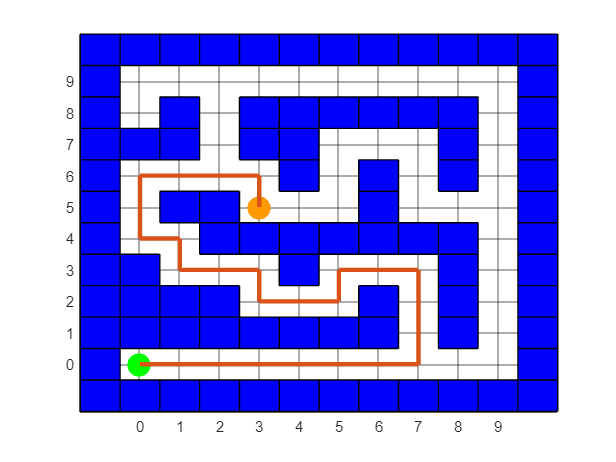

% Draw the map
% Draw a figure to show the map and process
plot_route(route, 1)

## Exercise 6.2: Controller